clc
clear

% Loading image
image_path = 'CROP1_47.tiff';
hcube = imread(image_path);

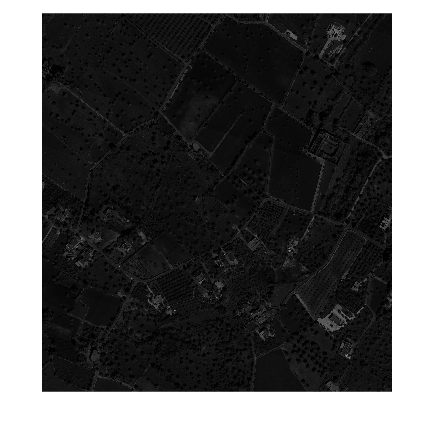

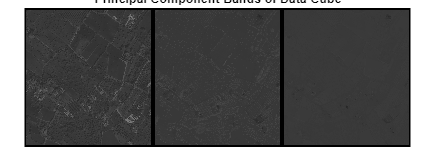

% Calculating PCA
[image,components] = PCA(hcube,5);

% Reshaping image
pixels = reshape(image, [], size(image, 3));

% DBSCAN clustering
epsilon = 0.5; % Define the maximum distance between two samples for them to be clustered in the same neighborhood.
MinPts = 5; % Define the number of samples in a neighborhood for a point to be considered as a core point.

% Perform DBSCAN clustering
idx = dbscan(pixels, epsilon, MinPts);

% Obtaining image's sizes
[rows, cols, ~] = size(image);

image = reshape(idx, [rows, cols]);

% Plot results
figure;
imshow(reshape(idx, [rows, cols]), []);
colormap(jet(max(idx))); % Use the maximum cluster label to define the colormap range
colorbar;
title('DBSCAN clustering results');
